Initialization

nullIdx = [];
numCarr = 2048;
cycPre = numCarr/16;
modOrder = 4;  % for 4-QAM
pilot_len = 16;
bitsPerSymbol = log2(modOrder)

bitsPerSymbol = 2


GB_len = numCarr/16;
left_gb = 1:GB_len

left_gb =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


right_gb = (numCarr-GB_len+1):numCarr

right_gb =         1921        1922        1923        1924        1925        1926        1927        1928        1929        1930        1931        1932        1933        1934        1935        1936        1937        1938        1939        1940        1941        1942        1943        1944        1945        1946        1947        1948        1949        1950        1951        1952        1953        1954        1955        1956        1957        1958        1959        1960        1961        1962        1963        1964        1965        1966        1967        1968        1969        1970


if mod(numCarr,2) == 0
    mid_guard = (numCarr/2)+1
else
    mid_guard = (numCarr+1)/2
end

mid_guard = 1025


nullIdx = [left_gb, mid_guard, right_gb]'

nullIdx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


numDataCarrs = numCarr-length(nullIdx)

numDataCarrs = 1791

Integrated Pilot

%generate pilot
my_pilot_len = pilot_len * bitsPerSymbol *2

my_pilot_len = 64

pilot = randi([0,1],my_pilot_len,1)

pilot =      1
     1
     0
     1
     1
     0
     1
     1
     0
     1



%set pilot location
intervial = round((numCarr - length(nullIdx))/(my_pilot_len/bitsPerSymbol))

intervial = 56

pilot_place = 1:intervial:1+intervial*(2*pilot_len-2)

pilot_place =            1          57         113         169         225         281         337         393         449         505         561         617         673         729         785         841         897         953        1009        1065        1121        1177        1233        1289        1345        1401        1457        1513        1569        1625        1681


pilot_place = [pilot_place';numCarr - length(nullIdx)]

pilot_place =      1
    57
   113
   169
   225
   281
   337
   393
   449
   505


pilotIdx = pilot_place

pilotIdx =      1
    57
   113
   169
   225
   281
   337
   393
   449
   505



my_pilot_place =[]


my_pilot_place =

     []



%set pilot bits location
for i = 1:bitsPerSymbol
    my_pilot_place = sort([my_pilot_place;bitsPerSymbol.*pilot_place-i+1]);
end;
pilot_place = my_pilot_place

pilot_place =      1
     2
   113
   114
   225
   226
   337
   338
   449
   450


bit_place = (1:(numCarr - length(nullIdx))*bitsPerSymbol)'

bit_place =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


bit_place(pilot_place) = []

bit_place =      3
     4
     5
     6
     7
     8
     9
    10
    11
    12



% numDataCarrs = numCarr-length(nullIdx)

My_data = randi([0,1],numDataCarrs*bitsPerSymbol,1)

My_data =      1
     1
     1
     1
     1
     0
     0
     0
     1
     0


My_data(pilot_place) = pilot

My_data =      1
     1
     1
     1
     1
     0
     0
     0
     1
     0


size(My_data)

ans =         3582           1


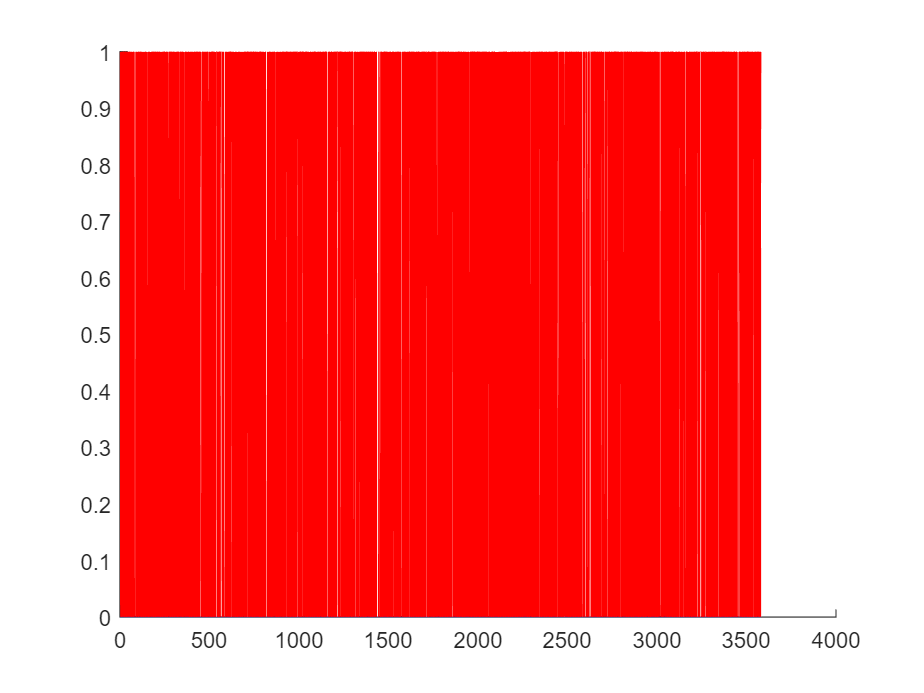


save('D:\Bristol\23-24\Project\Hardware\Simpler\Tx2\4QAM\My_data.mat', 'My_data','pilot','pilotIdx','pilot_place');

hold on
plot(real(My_data),'r')
plot(imag(My_data),'b')
hold off


temp = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx2\4QAM\My_data.mat','My_data','pilot','pilotIdx','pilot_place')

temp = 包含以下字段的 struct :
        My_data: [3582×1 double]
          pilot: [64×1 double]
       pilotIdx: [32×1 double]
    pilot_place: [64×1 double]


My_data = temp.My_data

My_data =      1
     1
     1
     1
     1
     0
     0
     0
     1
     0


read_pilot = temp.pilot

read_pilot =      1
     1
     0
     1
     1
     0
     1
     1
     0
     1


read_pilot_place = temp.pilot_place

read_pilot_place =      1
     2
   113
   114
   225
   226
   337
   338
   449
   450


read_pilotIdx = temp.pilotIdx

read_pilotIdx =      1
    57
   113
   169
   225
   281
   337
   393
   449
   505


Individual Pilot Frame

% My_data = randi([0,1],numDataCarrs*bitsPerSymbol,1)
% size(My_data)
% 
% save('D:\Bristol\23-24\Project\Hardware\Simpler\Tx2\4QAM\My_data.mat', 'My_data');
% 
% hold on
% plot(real(My_data),'r')
% plot(imag(My_data),'b')
% hold off
% 
% temp = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx2\4QAM\My_data.mat','My_data')
% My_data = temp.My_data